# Tarea: Regresión lineal

#### Juan Uriel Legaria Peña

#### Maestría en Ciencia e Ingeniería de la Computación

#### Aprendizaje Computacional 

### 0.- Implementación

La implementación se hizo utilizando un paradigma de programación orientada a objetos. Las clases implementadas y como se conectan entre sí se describe a continuación:

- WeatherData: Esta es la clase dedicada al manejo de los datos de clima de Szeged que se descargaron. Contiene un método getVariableData, el cual regresa un vector con la serie de tiempo de la variable que pida el usuario. El tipo de variable se establece dando como argumento un objeto de enumeración de tipo VariableType, algunos de los valores disponibles son: VariableType.TEMPERATURE, VariableType.PRESSURE, VariableType.HUMIDITY, VariableType.PRECIP_TYPE.

- Statistics: Es la clase auxiliar que se implementó para realizar algunas tareas de naturaleza estadística, tales como el cálculo de media, mediana, moda, desviación estándar y el coeficiente de correlación de pearson. 

- DataPrecook: Aquí se encapsularon los métodos de preparación de datos a llevar a cabo antes de introducirlos en el modelo, tales como la normalización de las variables, la separación en datos de entrenamiento y validación, y finalmente la imputación. Esta última se especifica utilizando objetos de tipo ImputationType, las opciones con las que se cuenta son: ImputationType.MEAN, ImputationType.MEDIAN, ImputationType.MODE, ImputationType.ELIMINATION.

- beta = resultsTrainingSet*trainingSet'*inv(trainingSet*trainingSet')

- LinearModelFitter: Esta es la clase que realiza el ajuste de un modelo lineal a los datos suministrados. Esta cuenta con dos métodos: fitByLeastSquares, el cual calcula los parámetros analíticamente mediante la relación: $\beta ={\mathrm{YX}\left(X\;X^t \right)}^{-1}$, y fitByGradientDescent, el cual utiliza el método del descenso de gradiente. 

### 1.- Relaciones entre variables

**¿Existe una relación entre la humedad y la temperatura?**

Aquíel tipo de relación en el que nos concentraremos será de tipo lineal. Para comenzar a contestar la pregunta calcularemos el coeficiente de correlación de pearson para ambas variables. Antes sin embargo, convendrá hacer una normalización de las mismas, para ello usaremos uno de los métodos provistos por nuestra clase DataPrecook.

%Obtenemos las series de tiempo de las variables de interés
data = WeatherData();
humidity = data.getVariableData(VariableType.HUMIDITY)';
temperature = data.getVariableData(VariableType.TEMPERATURE)';


%normalizamos
dataCooker = DataPrecook();
normalizedHumidity = dataCooker.normalizeVariable(humidity);
normalizedTemperature = dataCooker.normalizeVariable(temperature);

%Obtenemos el coeficiente de correlación de Pearson
stats = Statistics();
pearson = stats.getPearsonCorrelation(normalizedHumidity, normalizedTemperature);
disp("El coeficiente de correlación es: "+string(pearson));

El coeficiente de correlación es: -0.63225


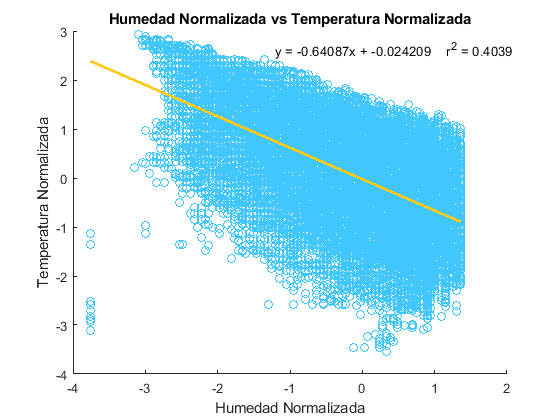

%Obtengamos ahora cual sería la regresión entre ambas variables 
%(datos de entrenamiento: 80% de todos los datos)
[trainingData, trainingDataResults, validationData, validationDataResults] = dataCooker.splitData(normalizedHumidity, normalizedTemperature, 0.2);
fitter = LinearModelFitter();
%Hagamoslo por descenso de gradiente para ver la gráfica de desempeño con
%los datos de validación
epochs = 1000;
learningRate = 0.01;
[beta, performanceTraining, performanceValidation, rSquared] = fitter.fitByGradientDescent(epochs, learningRate, trainingData, trainingDataResults, validationData, validationDataResults);
%Gráfico de la linea 
fitter.plotModel2D(normalizedHumidity, normalizedTemperature,beta,rSquared,"Humedad Normalizada", "Temperatura Normalizada");

El coeficiente de correlación indica que existe una relación moderada entre las dos variables (coeficiente de pearson de -0.63), donde la relación sería de proporcionalidad inversa en este caso. Sin embargo, como observamos en la figura anterior, el coeficiente de determinación indica que la proporción de varianza de la variable dependiente (Temperatura) que es explicable a partir de la variable independiente (Humedad) es tan solo de 0.4. Por lo que no es posible predecir con fiabilidad la temperatura a partir de la humedad. Esto también debería verse reflejado en el desempeño del modelo, el cual graficamos a continuación:

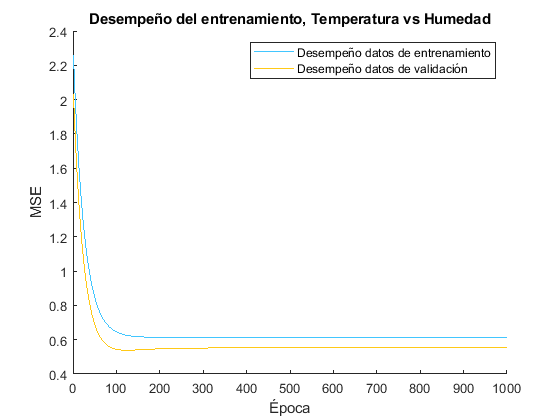

epochArray = 1:epochs;
figure()
hold on 
title("Desempeño del entrenamiento, Temperatura vs Humedad")
plot(epochArray, performanceTraining, 'Color', '#42c6ff')
plot(epochArray, performanceValidation,'Color','#ffc917')
ylabel('MSE')
xlabel('Época')
hold off
legend('Desempeño datos de entrenamiento','Desempeño datos de validación')

**¿Existe una relación entre la humedad y la temperatura aparente?**

Hagamos el mismo análisis con las nuevas variables.

%Obtenemos las series de tiempo de las variables de interés
data = WeatherData();
humidity = data.getVariableData(VariableType.HUMIDITY)';
apparentTemperature = data.getVariableData(VariableType.APPARENT_TEMPERATURE)';


%normalizamos
dataCooker = DataPrecook();
normalizedHumidity = dataCooker.normalizeVariable(humidity);
normalizedApparentTemperature = dataCooker.normalizeVariable(apparentTemperature);

%Obtenemos el coeficiente de correlación de Pearson
stats = Statistics();
pearson = stats.getPearsonCorrelation(normalizedHumidity, normalizedApparentTemperature);
disp("El coeficiente de correlación es: "+string(pearson));

El coeficiente de correlación es: -0.60257


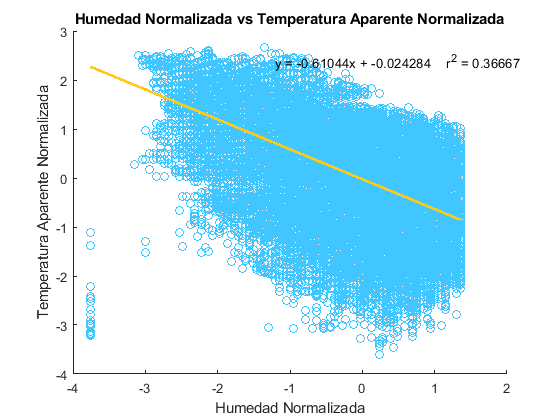


%Obtengamos ahora cual sería la regresión entre ambas variables 
%(datos de entrenamiento: 80% de todos los datos)
[trainingData, trainingDataResults, validationData, validationDataResults] = dataCooker.splitData(normalizedHumidity, normalizedApparentTemperature, 0.2);
fitter = LinearModelFitter();
%Hagamoslo por descenso de gradiente para ver la gráfica de desempeño con
%los datos de validación
epochs = 1000;
learningRate = 0.01;
[beta, performanceTraining, performanceValidation, rSquared] = fitter.fitByGradientDescent(epochs, learningRate, trainingData, trainingDataResults, validationData, validationDataResults);
%Gráfico de la linea 
fitter.plotModel2D(normalizedHumidity, normalizedApparentTemperature,beta,rSquared,"Humedad Normalizada", "Temperatura Aparente Normalizada");

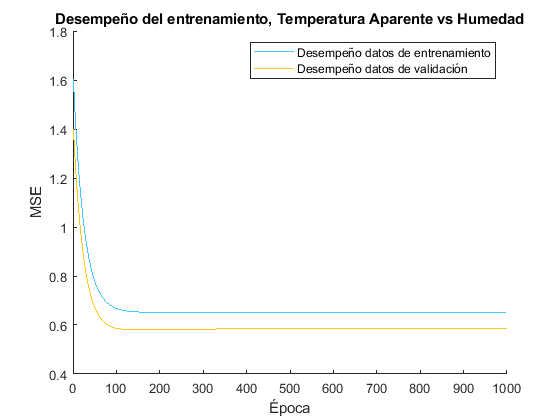

epochArray = 1:epochs;
figure()
hold on 
title("Desempeño del entrenamiento, Temperatura Aparente vs Humedad")
plot(epochArray, performanceTraining, 'Color', '#42c6ff')
plot(epochArray, performanceValidation,'Color','#ffc917')
ylabel('MSE')
xlabel('Época')
hold off
legend('Desempeño datos de entrenamiento','Desempeño datos de validación')

En este caso la correlación es casi la misma, sin embargo vemos incluso mayor variación de la temperatura aparente para cada valor de humedad. Esta observación viene sustentada por una disminución del coeficionete de determinación, el cual ahora toma un valor de 0.36. Lo anterior podría deberse a que la temperatura aparente considera una variable adicional: la velocidad del viento, lo cual añade incertidumbre al tratar de hacer predicciones con el modelo.

Solo como referencia, la temperatura aparente da una medida de cual es la temperatura que se percibe, considerando los cambios de presión del viento. En general si la velocidad del viento es alta tendremos una disminución en la presión, y en consecuencia una disminución local de temperatura. 

**¿Puedes predecir la temperatura aparente a partir de la humedad?**

No, ya que como mencionamos en el parrafo anterior,a pesar de que existe una moderada correlación entre ellas, existe demasiada variación en la temperatura aparente para cada valor de humedad, la cual se acompaña de un valor $R^2$ bajo. Aquí me parece que incluso podríamos pensarlo en terminos de información o energía. Lo que esta ocurriendo es que la humedad solo explica, o contribuye energeticamente con una porción pequeña a la variación de la temperatura aparente, mientras que el resto se debe a la influencia de otras variables, como son la velocidad del viento que mencioné antes.

### **2.- Regresión multiple **

#### **Generar un modelo de regresión múltiple para estimar el valor de la humedad en función de la presión y la temperatura**

#### **-Imputación por media**

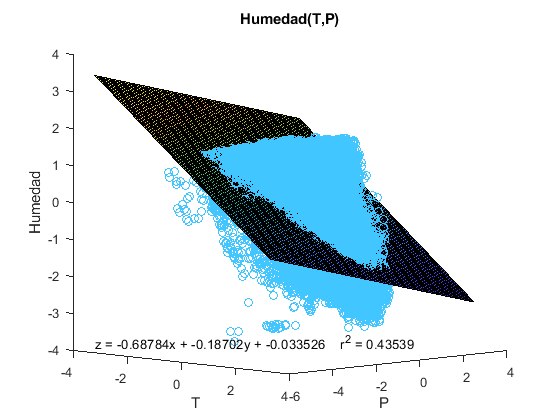

%Primero obtengamos las variables de interés y normalicemos
data = WeatherData();
humidity = data.getVariableData(VariableType.HUMIDITY);
temperature = data.getVariableData(VariableType.TEMPERATURE);
pressure = data.getVariableData(VariableType.PRESSURE);

%Imputamos por media 
dataCooker = DataPrecook();
M  = [humidity, temperature, pressure];
M = dataCooker.imputateData(ImputationType.MEAN,3,0,M);
humidity = M(:,1)';
temperature = M(:,2)';
pressure = M(:,3)';

%normalizamos
dataCooker = DataPrecook();
normalizedHumidity = dataCooker.normalizeVariable(humidity);
normalizedTemperature = dataCooker.normalizeVariable(temperature);
normalizedPressure = dataCooker.normalizeVariable(pressure);
normalizedTP = [normalizedTemperature; normalizedPressure];
%Obtenemos las fracciones de datos de entrenamiento y validación
[trainingData, trainingDataResults, validationData, validationDataResults] = dataCooker.splitData(normalizedTP, normalizedHumidity, 0.2);
%Entrenamos el modelo
epochs = 1000;
learningRate = 0.01;
fitter = LinearModelFitter();
[beta, performanceTraining, performanceValidation, rSquared] = fitter.fitByGradientDescent(epochs, learningRate, trainingData, trainingDataResults, validationData, validationDataResults);
fitter.plotModel3D(normalizedTemperature,normalizedPressure,normalizedHumidity,beta,rSquared,"T", "P", "Humedad");

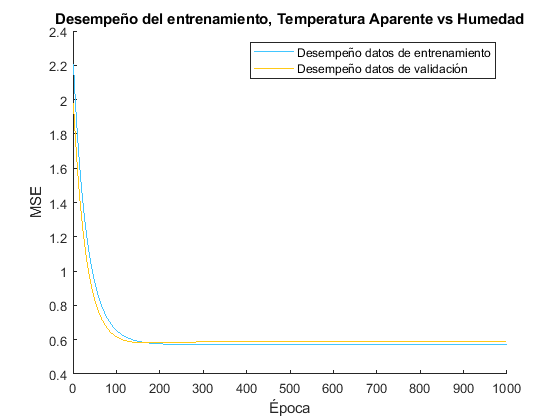

epochArray = 1:epochs;
figure()
hold on 
title("Desempeño del entrenamiento, Temperatura Aparente vs Humedad")
plot(epochArray, performanceTraining, 'Color', '#42c6ff')
plot(epochArray, performanceValidation,'Color','#ffc917')
ylabel('MSE')
xlabel('Época')
hold off
legend('Desempeño datos de entrenamiento','Desempeño datos de validación')

#### -Imputación por Mediana 

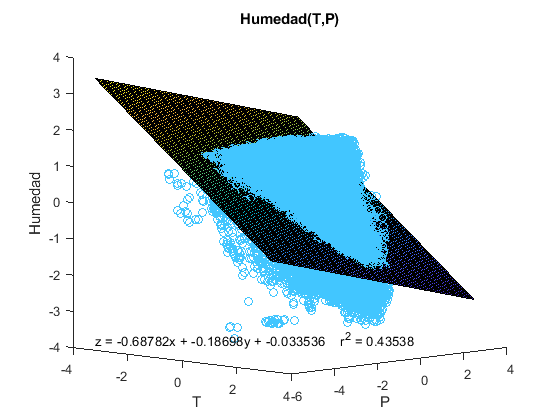

%Primero obtengamos las variables de interés y normalicemos
data = WeatherData();
humidity = data.getVariableData(VariableType.HUMIDITY);
temperature = data.getVariableData(VariableType.TEMPERATURE);
pressure = data.getVariableData(VariableType.PRESSURE);

%Imputamos por mediana
dataCooker = DataPrecook();
M  = [humidity, temperature, pressure];
M = dataCooker.imputateData(ImputationType.MEDIAN,3,0,M);
humidity = M(:,1)';
temperature = M(:,2)';
pressure = M(:,3)';

%normalizamos
dataCooker = DataPrecook();
normalizedHumidity = dataCooker.normalizeVariable(humidity);
normalizedTemperature = dataCooker.normalizeVariable(temperature);
normalizedPressure = dataCooker.normalizeVariable(pressure);
normalizedTP = [normalizedTemperature; normalizedPressure];

%Obtenemos las fracciones de datos de entrenamiento y validación
[trainingData, trainingDataResults, validationData, validationDataResults] = dataCooker.splitData(normalizedTP, normalizedHumidity, 0.2);

%Entrenamos el modelo
epochs = 1000;
learningRate = 0.01;
fitter = LinearModelFitter();
[beta, performanceTraining, performanceValidation, rSquared] = fitter.fitByGradientDescent(epochs, learningRate, trainingData, trainingDataResults, validationData, validationDataResults);

%Grafico del ajuste
fitter.plotModel3D(normalizedTemperature,normalizedPressure,normalizedHumidity,beta,rSquared,"T", "P", "Humedad");

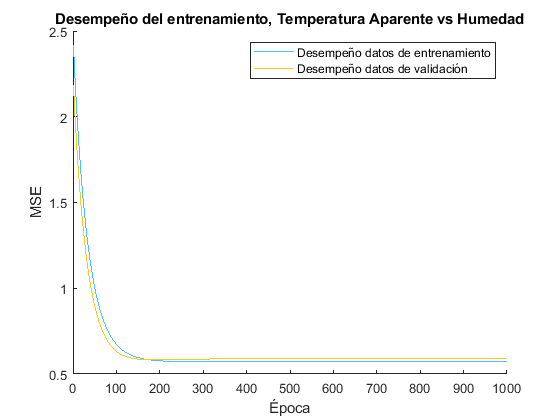

epochArray = 1:epochs;

%Grafico de desempeño
figure()
hold on 
title("Desempeño del entrenamiento, Temperatura Aparente vs Humedad")
plot(epochArray, performanceTraining, 'Color', '#42c6ff')
plot(epochArray, performanceValidation,'Color','#ffc917')
ylabel('MSE')
xlabel('Época')

hold off

legend('Desempeño datos de entrenamiento','Desempeño datos de validación')

#### **-Imputación por moda **

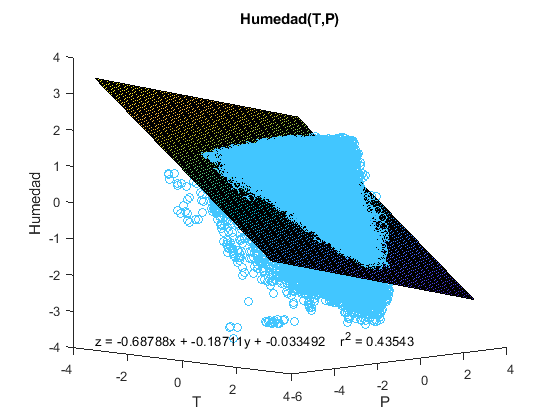

%Primero obtengamos las variables de interés y normalicemos
data = WeatherData();
humidity = data.getVariableData(VariableType.HUMIDITY);
temperature = data.getVariableData(VariableType.TEMPERATURE);
pressure = data.getVariableData(VariableType.PRESSURE);

%Imputamos por mediana
dataCooker = DataPrecook();
M  = [humidity, temperature, pressure];
M = dataCooker.imputateData(ImputationType.MODE,3,0,M);
humidity = M(:,1)';
temperature = M(:,2)';
pressure = M(:,3)';

%normalizamos
dataCooker = DataPrecook();
normalizedHumidity = dataCooker.normalizeVariable(humidity);
normalizedTemperature = dataCooker.normalizeVariable(temperature);
normalizedPressure = dataCooker.normalizeVariable(pressure);
normalizedTP = [normalizedTemperature; normalizedPressure];

%Obtenemos las fracciones de datos de entrenamiento y validación
[trainingData, trainingDataResults, validationData, validationDataResults] = dataCooker.splitData(normalizedTP, normalizedHumidity, 0.2);

%Entrenamos el modelo
epochs = 1000;
learningRate = 0.01;
fitter = LinearModelFitter();
[beta, performanceTraining, performanceValidation, rSquared] = fitter.fitByGradientDescent(epochs, learningRate, trainingData, trainingDataResults, validationData, validationDataResults);

%Grafico del ajuste
fitter.plotModel3D(normalizedTemperature,normalizedPressure,normalizedHumidity,beta,rSquared,"T", "P", "Humedad");

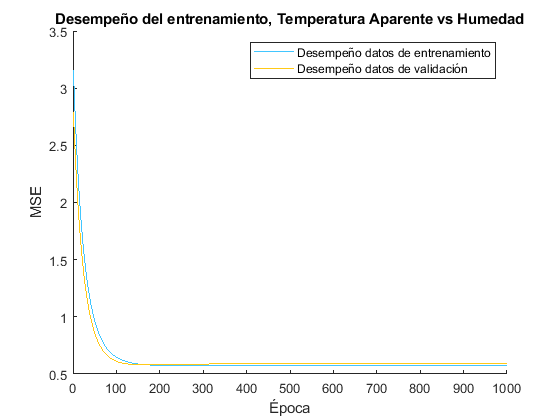

epochArray = 1:epochs;

%Grafico de desempeño
figure()
hold on 
title("Desempeño del entrenamiento, Temperatura Aparente vs Humedad")
plot(epochArray, performanceTraining, 'Color', '#42c6ff')
plot(epochArray, performanceValidation,'Color','#ffc917')
ylabel('MSE')
xlabel('Época')
hold off

legend('Desempeño datos de entrenamiento','Desempeño datos de validación')

### **-Imputación por eliminación**

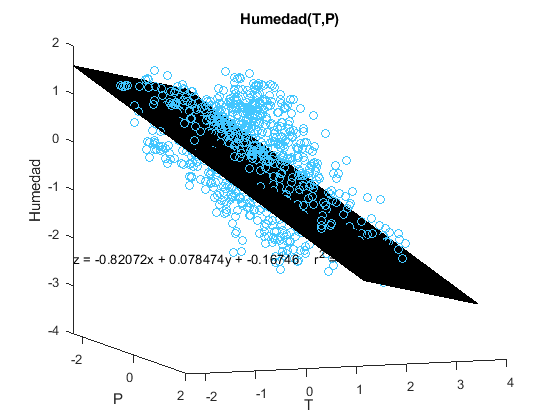

%Primero obtengamos las variables de interés y normalicemos
data = WeatherData();
humidity = data.getVariableData(VariableType.HUMIDITY);
temperature = data.getVariableData(VariableType.TEMPERATURE);
pressure = data.getVariableData(VariableType.PRESSURE);

%Imputamos por eliminación
dataCooker = DataPrecook();
M  = [humidity, temperature, pressure];
M = dataCooker.imputateData(ImputationType.ELIMINATION,3,0,M);
humidity = M(:,1)';
temperature = M(:,2)';
pressure = M(:,3)';

%normalizamos
dataCooker = DataPrecook();
normalizedHumidity = dataCooker.normalizeVariable(humidity);
normalizedTemperature = dataCooker.normalizeVariable(temperature);
normalizedPressure = dataCooker.normalizeVariable(pressure);
normalizedTP = [normalizedTemperature; normalizedPressure];

%Obtenemos las fracciones de datos de entrenamiento y validaciónk
[trainingData, trainingDataResults, validationData, validationDataResults] = dataCooker.splitData(normalizedTP, normalizedHumidity, 0.2);

%Entrenamos el modelo
epochs = 1000;
learningRate = 0.01;
fitter = LinearModelFitter();
[beta, performanceTraining, performanceValidation, rSquared] = fitter.fitByGradientDescent(epochs, learningRate, trainingData, trainingDataResults, validationData, validationDataResults);

%Grafico del ajuste
fitter.plotModel3D(normalizedTemperature,normalizedPressure,normalizedHumidity,beta,rSquared,"T", "P", "Humedad");

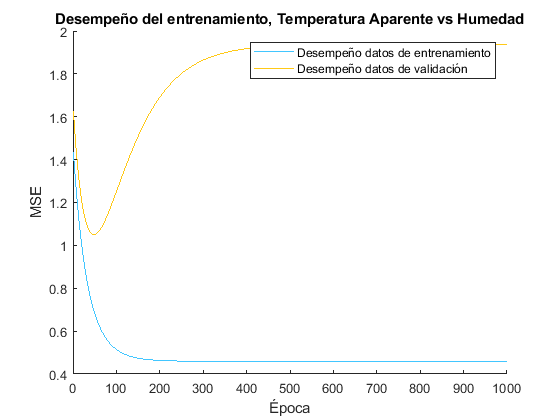

epochArray = 1:epochs;

%Grafico de desempeño
figure()
hold on 
title("Desempeño del entrenamiento, Temperatura Aparente vs Humedad")
plot(epochArray, performanceTraining, 'Color', '#42c6ff')
plot(epochArray, performanceValidation,'Color','#ffc917')
ylabel('MSE')
xlabel('Época')
hold off

legend('Desempeño datos de entrenamiento','Desempeño datos de validación')

Puede observarse que las 3 medidas de tendencia central utilizadas producen resultados similares para el ajuste. Esto sin embargo podría verse modificado para variables que presenten una gran asimetría en su distribución. Un contraste significativo sin embargo, se presenta al utilizar el método de eliminación de filas para imputar. Una mirada rápida al coeficiente de determinación nos haría pensar que este resulta en un mejor ajuste que en los demas casos ($R^2 =0\ldotp 5$), sin embargo al observar el desempeño del entrenamiento se observa que estamos en presencia de un caso de overfitting. Como se mencionó en clase este es un fenómeno que puede ocurrir cuando no contamos con una muestra suficientemente variada de datos para entrenar, es por ello que debemos proceder con precaución al utilizar métodos de imputación que acorten los datos.

Un detalle mas que se podría observar de los ajustes es que el agregar la presión para predecir la humedad, no incremente en forma demasiado significativa el poder de predicción del modelo. Esto puediese deberse a que la presión y la temperatura suelen relacionarse entre sí, (por ejemplo en un gas ideal en equilibrio la ecuación de estado es $\mathrm{pV}=\mathrm{nRT}$). Cosas posteriores que podriamos probar sería por ejemplo examinar correlaciones con mas variables, incorporando la información de la velocidad del viento, tipo de precipitación etc.